# Expand Example 2.10:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

In Example 2.10 we have found the response of the RC circuit shown below with element values R=1 $\Omega$ and $C=1/4$ F  to a pulse signal with amplitude $A$ and width $\lambda$, centered around the time origin (assume $y(0)=0$).

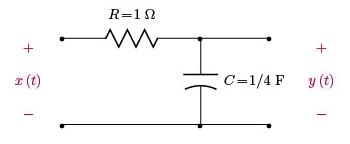

In Example 2.8, the unit step response of the same circuit was found to be

        $y(t)=(1-e^{-t/RC})\,u(t)$                    (2.51)

Using this result, determine and graph the response of this circuit to a bipolar pulse defined as

        
$$x(t)=\left\{
\begin{array}{c l}
1, & 0\le t<\lambda/2 \\
-1 & \lambda/2\le t<\lambda
\end{array}\right.$$


R = 1; % Resistance
C = 0.25; % Capacitance

lambda = 2.6; % Width of pulse

alpha = 1/(R*C);
yu = @(t) (1-exp(-alpha*t)).*(t>=0);  % Eqn. (2.51)

Compute and graph the bipolar pulse:

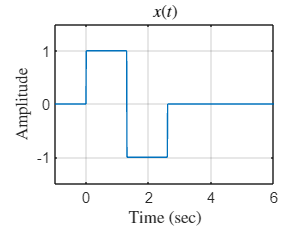

t = [-1:0.01:6];
x = ss_step(t)-2*ss_step(t-0.5*lambda)+ss_step(t-lambda);
plot(t,x); grid;
axis([-1,6,-1.5,1.5]);
set(0,'defaultTextInterpreter','latex');
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x(t)$');

Compute and graph the response:

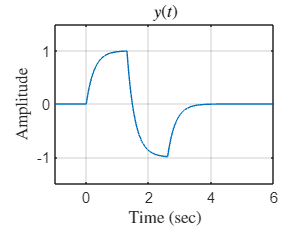

y = yu(t)-2*yu(t-0.5*lambda)+yu(t-lambda);
plot(t,y); grid;
axis([-1,6,-1.5,1.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$y(t)$');

set(0,'defaultTextInterpreter','tex');